scale = 1; 
shape = 0.5; 
location = 2;
pd = makedist('gp', shape, scale, location);
c = median(pd)

c = 2.8284

X = random(pd, 5000, 200);
mu_X = mean(mean(X))

mu_X = 4.0055


xhat_vec = (-4:0.01:5)';
L = length(xhat_vec);

Jvals = zeros(L,1);
for i = 1:L
    Jvals(i) = sum(sum(abs(X - xhat_vec(i)))) / (N*R) ;
end 
[min_val, i_x] = min(Jvals)

min_val = 16.6372

i_x = 684

min_x = xhat_vec(i_x)

min_x = 2.8300

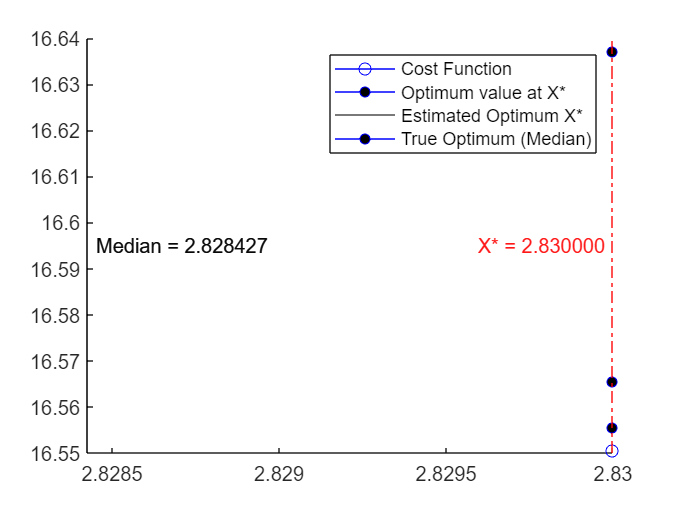


hold on

plot(min_x, min_val, 'bo-', 'MarkerSize', 5, 'MarkerFaceColor', 'k')
text(min_x + 0.2, min_val, ['Min of Cost Function at X*: ' num2str(min_val)], 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left', 'FontSize', 10)
label1 = {sprintf('Median = %f', c)};
xline(c, 'k', label1, 'LabelVerticalAlignment', 'middle', 'LabelHorizontalAlignment', 'right', 'LabelOrientation', 'horizontal');
label = {sprintf('X* = %f', min_x)};
xline(min_x, '-.r', label, 'LabelVerticalAlignment', 'middle', 'LabelHorizontalAlignment', 'left', 'LabelOrientation', 'horizontal');
legend('Cost Function', 'Optimum value at X*', 'Estimated Optimum X*', 'True Optimum (Median)')


Pr_opt = cdf(pd, 1.05*min_x) - cdf(pd, 0.95*min_x)

Pr_opt = 0.1004

Pr = cdf(pd, 1.05*mu_X) - cdf(pd, 0.95*mu_X)

Pr = 0.0501